# **Relational and Logical Operators**

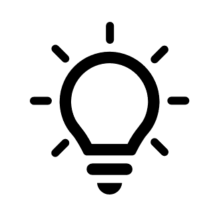 Where do I find MATLAB? [Here](https://www.mathworks.com/academia/tah-portal/wits-university-40783970.html)!

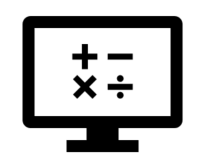 Do I have to have MATLAB installed on my computer right now? No, you can use  [MATLAB Online](https://matlab.mathworks.com/)!

## Recap of Week 2, Part 1: Arrays and Matrices

This week in part 1, we learnt about: 

- What arrays and matrices are

- Creating arrays

- Indexing into arrays 

- Concatenation of arrays

- Operating with function on arrays

In the next part of this week's content, we will be learning about relational and logical operators, covering the following sub-topics: 

- Introduction to decision making with operators 

- Relational operators

- Logical operators

## Decision Making with Operators 

### Introduction to decision making with operators

To give context to this section, we will be considering a packing shipping example. Let us call this company *Package Shippers*, who has worked out the most profitable price to charge their customers depending on the weight of the package they request to be couriered/shipped. For simplicities sake, let us assume that *Package Shippers* don't ship packages that weigh more than `2.5` kilograms. The formula they use is based on the following table:  

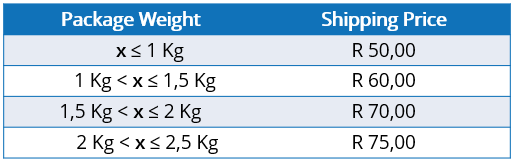

If a customer were to bring in a package that weighs `1.75` Kg, the shipping price that the customer would be charged is R 70.00. The process of determining this is easy for most humans because we understand relational and logical operators, i.e. determine what price the customer should be charged using the pricing rules described in the table above. 

Before we jump into how these operators are defined or used operators, let us consider our line of thinking when applying the pricing rules described in the table above. The weight of the package is supplied to us, and we determine which row of the Package Weight column the supplied weight fits. One could start at the top or the bottom row, asking for example "Is `1.75` Kg **less than or equal to** `1` Kg?". We know this is **not true**, so we move to the proceeding row, asking; "Is `1.75` Kg **greater than** `1` Kg **and**** less than or equal to** `1.5` Kg?", and so on. Once we find the pricing rule question that is true, we then refer to the Shipping Price in that same row. The illustration below helps visualise this graphically. 

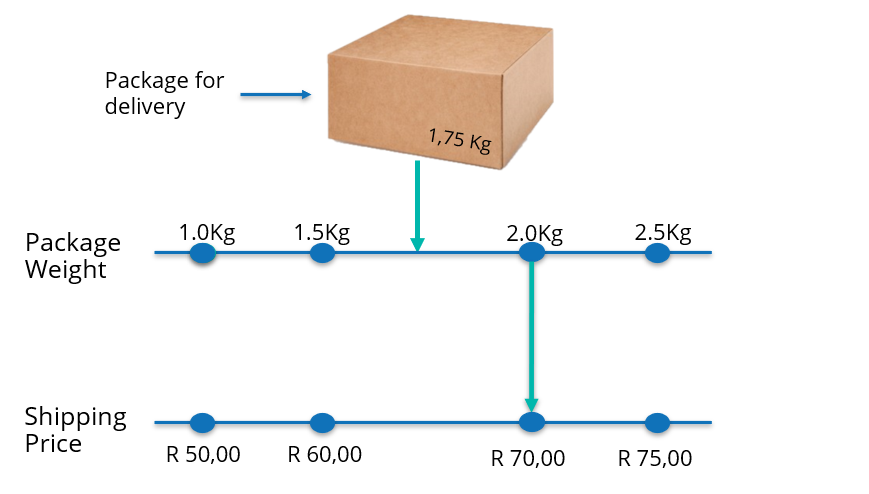

When values or numbers are being compared, for example "Is `1.75` Kg **less than or equal to** `1` Kg?", we are making use of a relational operator, "**less than or equal to**"/$\le$. The outcome to a statement that includes a relational operator is always logical, i.e. a true or false, and we can combine two or more logical outcomes by means of a logical operator (**and**/**or**), for example "Is `1.75` Kg greater than 1 Kg **and **less than or equal to `1.5` Kg?". 

### Relational Operators 

Relational operators, also known as conditional operators, are used to **compare two variables/values** to determine if the condition is true or false, for example the outcome of $\pi \ge 3$ would be true while the outcome of $\pi \le 3$ would be false. The outcomes of such statements are logical values which can only take on a value of 1 (when true) and 0 (when false). The following table has the relational operators you'll need for programming:

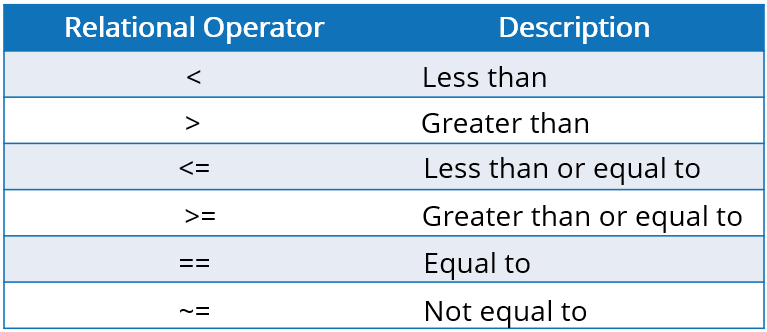

Let us put these into practice by considering the example mentioned above:

pi >= 3
pi <= 3

Note: The outputs are of type logical.

Now you try! As with functions, relational operators can also be applied to arrays, let us demonstrate this through some exercises. Let us consider two randomly generated integer vectors `arr_1` and `arr_2:`

arr_1 = randi(50,[1 10])

ans = logical
   1

arr_2 = randi(50,[1 10])

ans = logical
   0

Which elements of `arr_1` is greater than or equal to the corresponding element in `arr_2`? Assign the answer to the variable `logical_arr_1` for use later on`.`

Which elements of `arr_2` is greater than `10`? Assign the answer to the variable `logical_arr_2` for use later on.

Now you try! In the two exercise questions above, we saw the application of relational operators to the vector arrays. Now, let us consider two exercises that demonstrate the application of relational operators on matrix arrays. Consider the following two randomly generated integer matrices, `arr_3` and `arr_4`:

arr_3 = randi(50,[4 4])
arr_4 = randi(50,[4 4])

Which elements of `arr_3` is less than their corresponding elements in `arr_4`?

Which elements of `arr_4` is greater than or equal to `20`?

Note: Relational operators can be applied to arrays of any order. We only covered the application of relational operators in the case of scalar, vector, and matrix arrays. Consult the documentation for the [Array Comparison with Relational Operators](https://www.mathworks.com/help/matlab/matlab_prog/array-comparison-with-relational-operators.html) for more information. 

**Wondering where you encounter relational operators in your everyday life?**

A relational operator is applied when a comparison or relation between two variables/values is required. In life, we continuously make decisions around time, place, factors in our environments or our personal experiences. We get to define our morning alarm time, where our favourite reading spot is, how loud to play our music, and so on. These decisions are always made with some frame of reference in mind, like the time of day, the position we are located on Earth, the level of stimulation our unique bodies experience, etc. These frames of reference can be seen as one of the entities we compare with or relate to, in order to make our decisions. 

If you got lost in the explanation above, let us consider a particular example to focus on. Imagine that we are looking to purchase and sell bread rolls for a profit. Each bread roll costs us ZAR 5.00

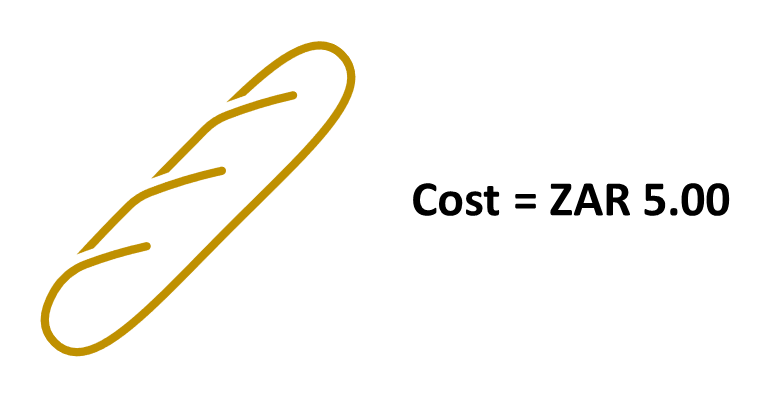

Two potential customers approach us with an offer. The first potential customer offers us ZAR 4.50 for a bread roll, the second offers us ZAR 8.00 for a bread roll. As we are selling bread rolls with the intention of making a profit, we would reject the offer made by the first potential customer and accept the offer from the second one. This is because the selling price must be greater than our cost price in order for us to generate profit from the transaction. 

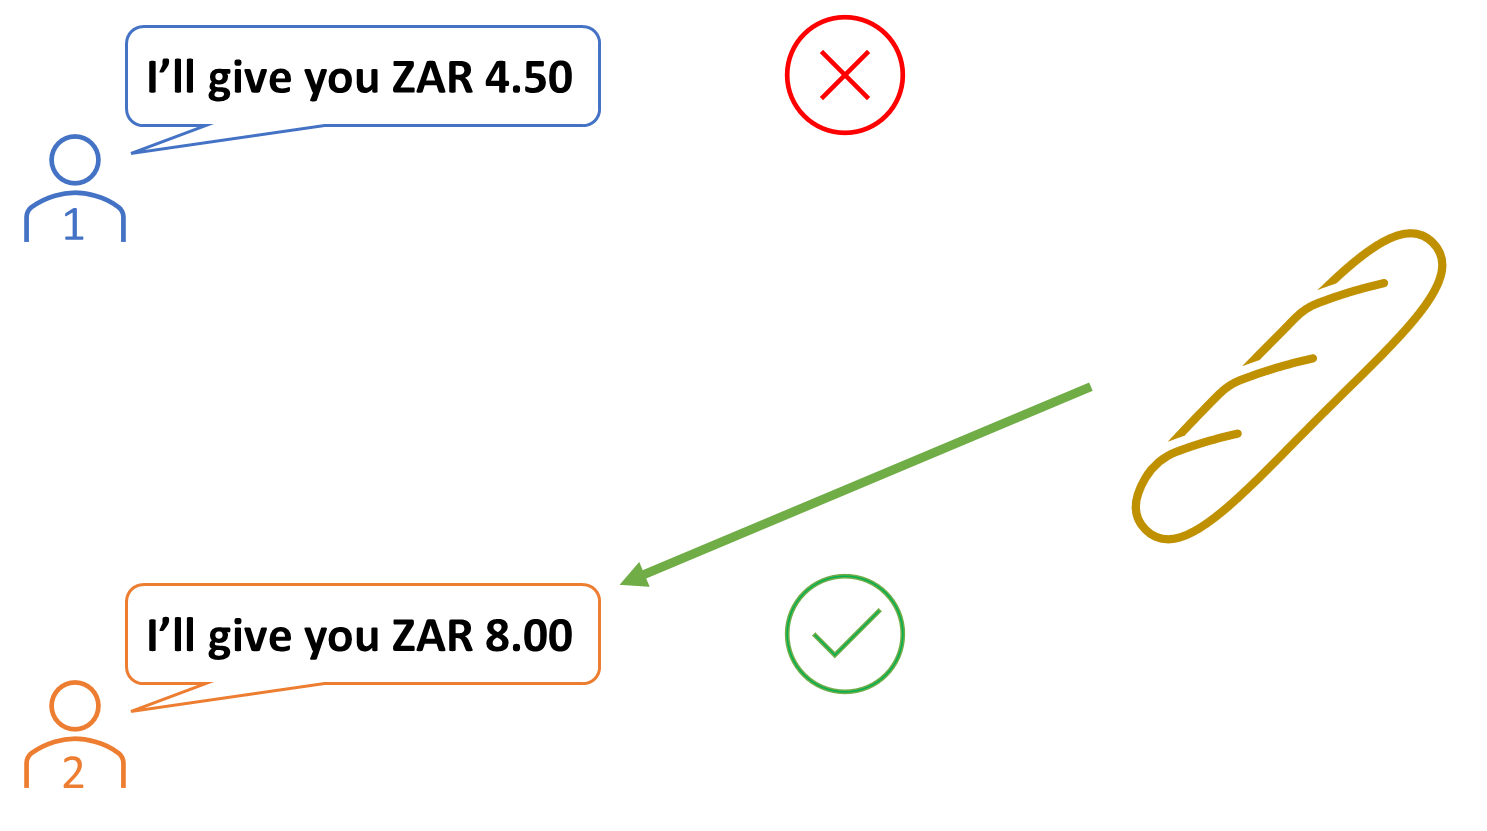

Let us consider the line of thinking that our brains might follow when choosing to accept or reject the offers. Assume that the question we ask ourselves is, "Is this offer profitable?". If this is true, we would consequently accept the offer, and if it is false, we will reject the offer. Begin by defining our cost price and the two offers we receive:  

Cost_price_in_ZAR = 5.0;
Offer_1_in_ZAR = 4.5;
Offer_2_in_ZAR = 8.0;

Let us test is each of the offers are greater than our cost price:

Is_Offer_1_Profitable = Offer_1_in_ZAR > Cost_price_in_ZAR
Is_Offer_2_Profitable = Offer_2_in_ZAR > Cost_price_in_ZAR

We received a logical response for `Is_Offer_1_Profitable `of `0`, indicating false, i.e. we should reject the first offer. For the second offer, we received a logical response for `Is_Offer_2_Profitable` of `1`, indicating true, i.e. we should accept the second offer.

### Logical Operators

Logical operators are used to **compare two statements** to determine if the condition is true or false. As with relational operators, the outcome of a comparison using a logical operator will be of type logical, which can only take on a value of 1 (when true) and 0 (when false). The following table has the basic logical operators you'll need for programming:

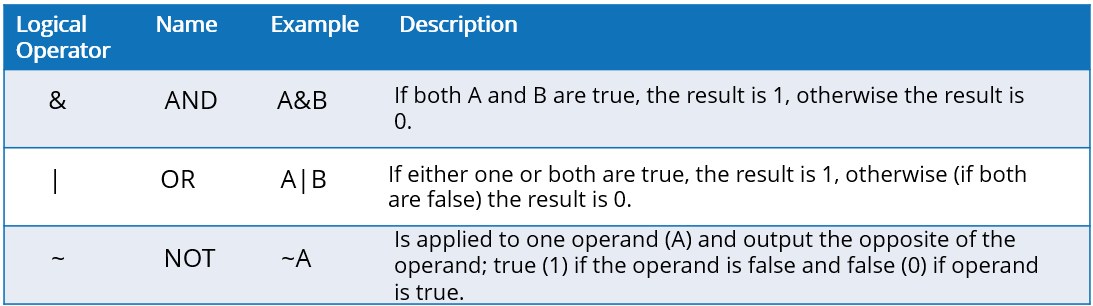

These operators can be applied to scalars and arrays of higher orders/dimensions. Let us consider the above-mentioned operators to `logical_1` and `logical_2` as defined below: 

logical_1 = true;
logical_2 = false;
logical_1 & logical_2

Is_Offer_1_Profitable = logical
   0

logical_1 | logical_2

Is_Offer_2_Profitable = logical
   1

~logical_1

In a similar way, we can apply logical operators on logical arrays, of any order. Recall the logical arrays we computed in the previous subsection, `log_arr_1` and `log_arr_2`, let us apply the `&` operator to them.

logical_arr_1
logical_arr_2
logical_arr_1 & logical_arr_2

ans = logical
   0

Note: If you have cleared your workspace, you will need to run the section where `logical_arr_1` and `logical_arr_2` are defined. The logical arrays produced will be different each time you run the section, this is because they are based on randomly generated integer arrays.

Now you try! Create a row vector, `arr_5`, with 5 elements between the values of `1` and `10` using the `randi` function. Determine which elements are smaller than `4` or greater than `6`.

ans = logical
   1

ans = logical
   0

**Wondering where you encounter logical operators in your everyday life?**

The decisions we make every day are often complex and based on several factors/conditions. In the relational operators section, we considered the most simple form of decision making, i.e. there are two values/quantities that were being compared. Here, we will be considering an instance where two outcomes of relational operator conditions are combined to make a decision. The key here is that two statements are being compared instead of two variables/values. 

Let us consider a decision where we choose to light a candle or not for our study area. Let us consider a case where we have access to an electric light and a candle (with a working lighter) as the two sources of light in our study area. Taking the decision to light the candle would depend on if we have an electricity supply or not, and if we require light in your study at the time (how dark the environment is). Let us define these conditions as yes or no questions:

- Does the study area have sufficient light? 

- Do we have an electricity supply available? 

We assume that there is only one reason why you would light a candle to be used as light source, this is when both questions (conditions) are answered with a "no", i.e. the study area does not have sufficient light, **and** we do not have an electricity supply available. The other combinations of outcomes can be summarised as follows: 

- If there is not sufficient light in the study area and we have an electricity supply, then we can use out electric light 

- If there is sufficient light available in the study area, then there is no need to light a candle or to use an electric light. 

Let us represent the combinations of condition outcomes and the decision taken in an illustrative manner. Note that we depict an answer of "yes" to either of the questions by a green icon, and an answer of "no" by a red icon.

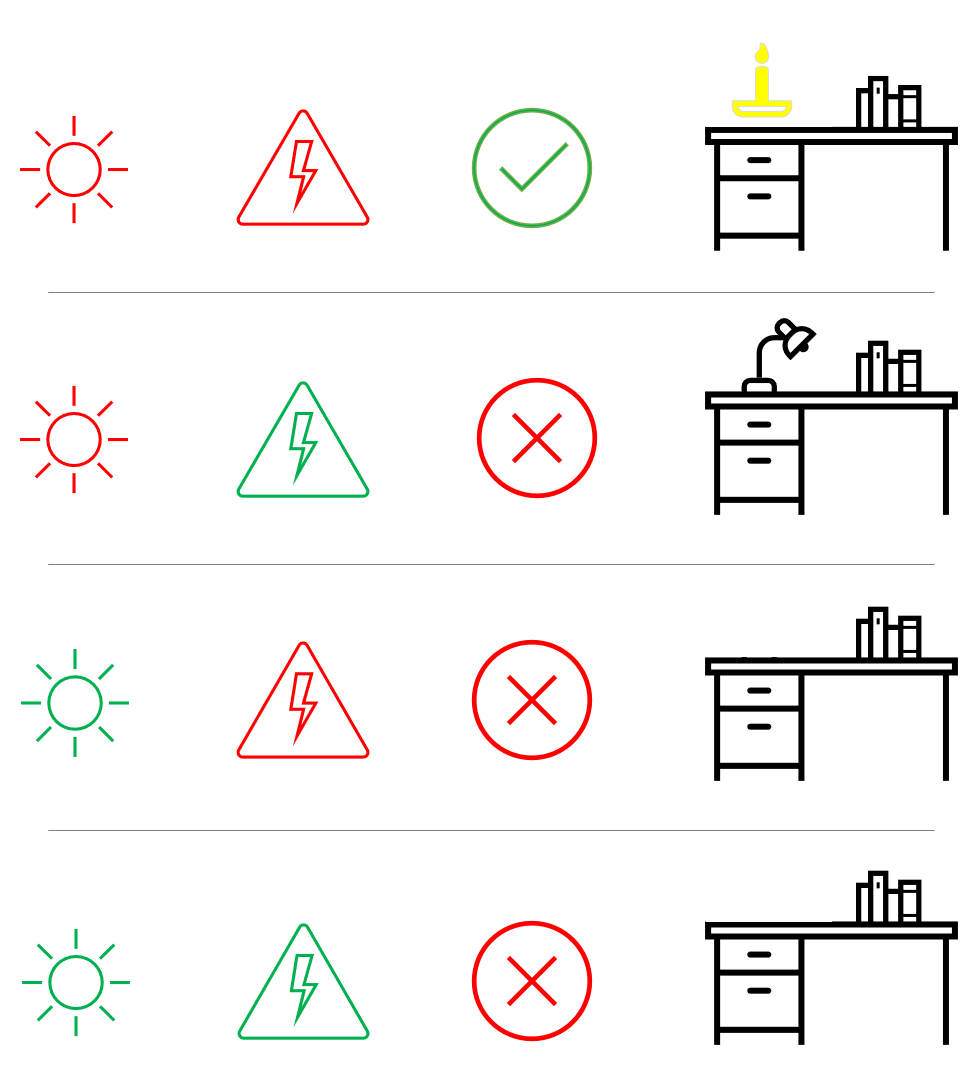

Let us now define this using some code. We assume that an answer of "yes" and "no" are `true` and `false,` respectively.

Question_1_Answer = true;

logical_arr_1 = 1×10 logical array
   1   1   0   0   1   0   1   0   1   1


Question_2_Answer = true;

logical_arr_2 = 1×10 logical array
   1   1   0   0   0   0   0   0   0   0


Should we light a candle for our study area? 

~Question_1_Answer && ~Question_2_Answer

ans = 1×10 logical array
   1   1   0   0   0   0   0   0   0   0


ans = logical
   0

## What we've covered this week in part 2: Relational and Logical Operators

This week in part 2, we learnt about: 

- What arrays and matrices are

- Creating arrays

- Indexing into arrays 

- Concatenation of arrays

- Operating with function on arrays

In the next part of this week's content, we will be learning about relational and logical operators, covering the following sub-topics: 

- Introduction to decision making with operators 

- Relational operators

- Logical operators

## Extra resources

- [Documentation: MATLAB Fundamentals](https://matlabacademy.mathworks.com/artifacts/quick-reference.html?course=mlbe&release=R2020b&language=en&) 

- [Documentation: Find Array Elements That Meet a Condition](https://www.mathworks.com/help/matlab/matlab_prog/find-array-elements-that-meet-a-condition.html)

- [Documentation: Logical Operators: Short-Circuit && ||](https://www.mathworks.com/help/matlab/ref/logicaloperatorsshortcircuit.html)

- [MATLAB Fundamentals Self-paced Course](https://matlabacademy.mathworks.com/details/matlab-fundamentals/mlbe)

- [Self-Paced Online Courses](https://matlabacademy.mathworks.com/)

## References

- [Documentation: MATLAB Fundamentals](https://matlabacademy.mathworks.com/artifacts/quick-reference.html?course=mlbe&release=R2020b&language=en&) 

***Copyright 2022 The MathWorks, Inc. & Opti-Num Solutions (Pty) Ltd. ***